Select a folder and calculate average Lab-value for each image.

**Do not run unless u want tro try another folder**

folder = "Images/flower"; % locate folder
name = 'labValuesFlowers.mat';
calculateLabValues(folder, name);

100%
All Lab values has been stored
Elapsed time is 13.480652 seconds.


clear all;
% Estimated run time: 1 minute.

Select an image to reproduce and reproduce it!

tempWidth = 125

tempHeight = 189

width = 125

height = 190

Image is smaller than 100px, scaling performed. consider using larger picture


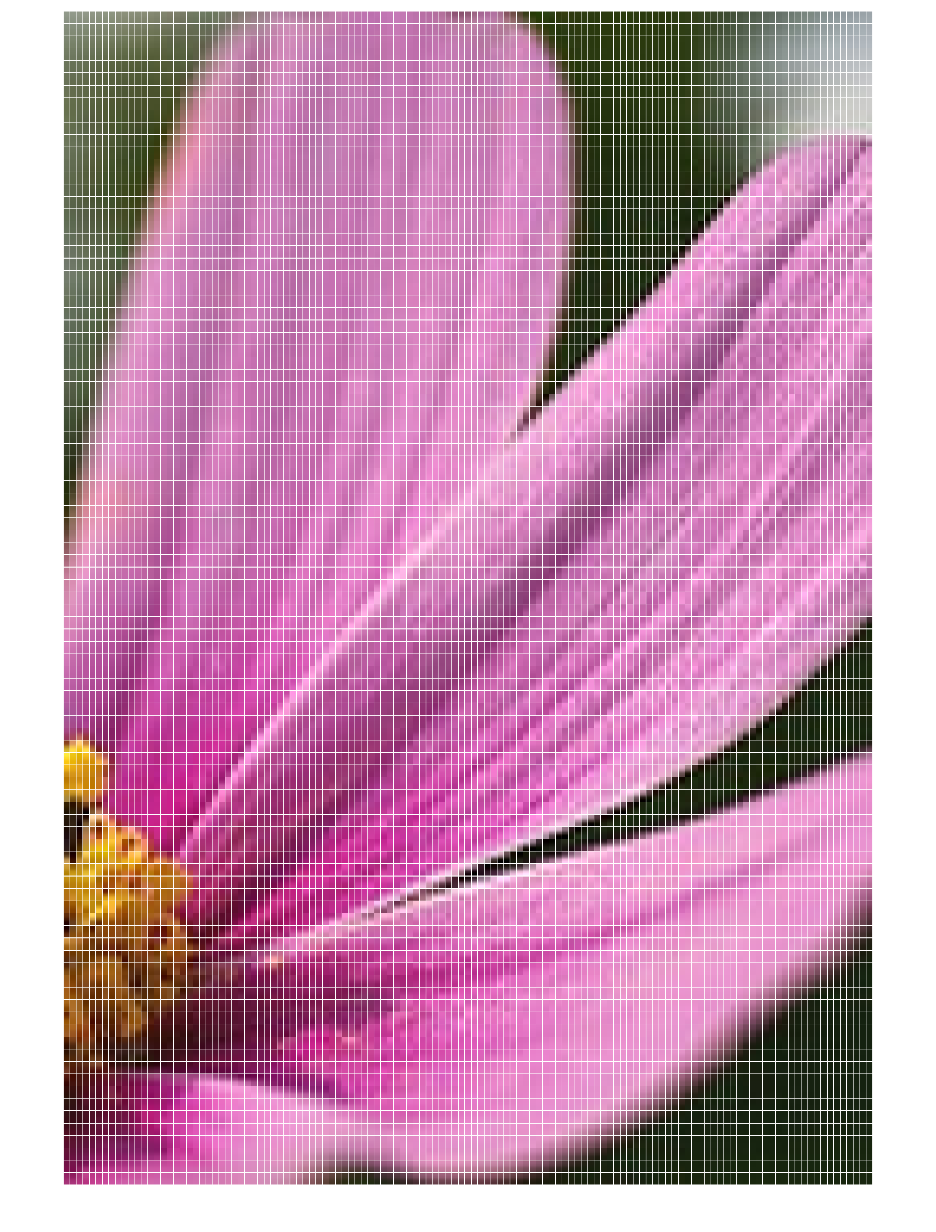

Elapsed time is 56.148793 seconds.


I = imread('Images/flower/flower_0066.jpg');
name = 'reproduced_flower_0066.jpg';
numberOfColors = 10;
imagesPerColor = 1;
reproducedImage = reproduceImage(I,name, numberOfColors, imagesPerColor);

% Estimated run time: 194 seconds

imageSize = size(reproducedImage);
I = im2double(I);
I = imresize(I, [imageSize(1) imageSize(2)], 'bicubic');

[SCIELAB,SSIM,SNR] = qualityMeasure(I,reproducedImage)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


SCIELAB = 2.0870

SSIM = 0.4381

SNR = 8.4113

I = imread('Images/flower/flower_0066.jpg');
I = im2double(I);
imageSize = size(I);
reproducedImage2 = reproducedImage;
reproducedImage2 = imresize(reproducedImage2, [imageSize(1) imageSize(2)], 'bicubic');
[SCIELAB,SSIM,SNR] = qualityMeasure(I,reproducedImage2)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


SCIELAB = 1.1409

SSIM = 0.8471

SNR = 14.6051

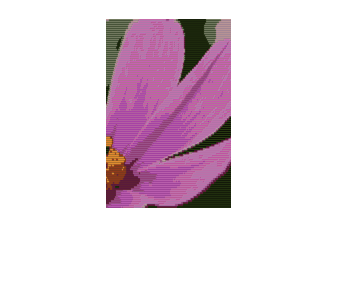


figure;
imshow(reproducedImage2)

I = imread('Images/flower/flower_0066.jpg');
I = im2double(I);
imageSize = size(I);
reproducedImage2 = reproducedImage;
reproducedImage2 = imresize(reproducedImage2, [imageSize(1) imageSize(2)], 'bilinear');
[SCIELAB,SSIM,SNR] = qualityMeasure(I,reproducedImage2)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


SCIELAB = 1.1449

SSIM = 0.8627

SNR = 14.8140

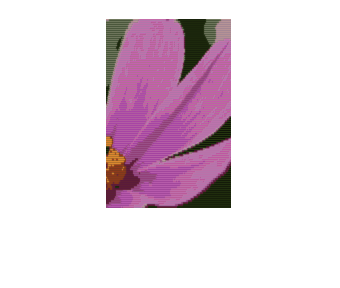


figure;
imshow(reproducedImage2)